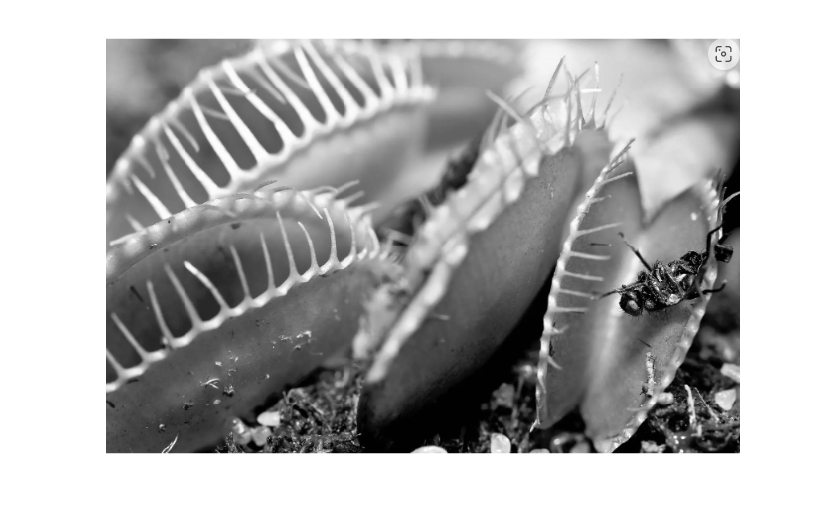

% Capítulo 5: Segmentación y tratamiento de imágenes binarias 
Image      = abreimagen();
Gray_Image = rgb2gray(Image);
imshow(Gray_Image)

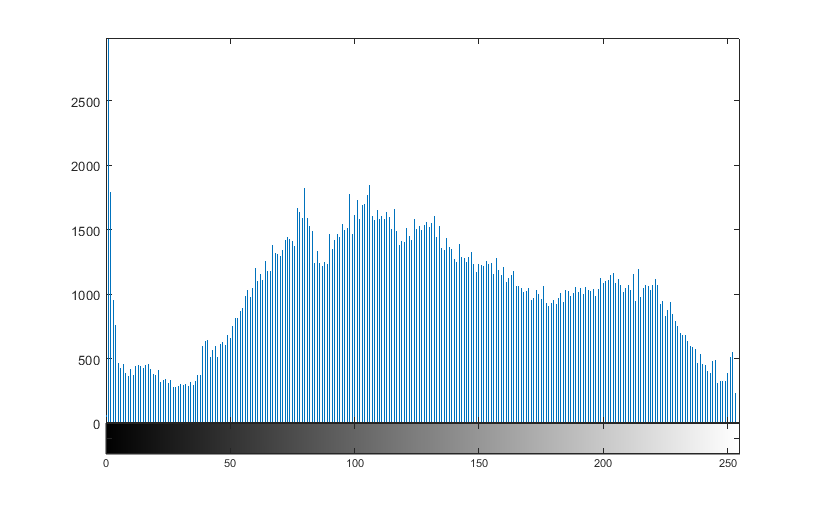

imhist(Gray_Image)

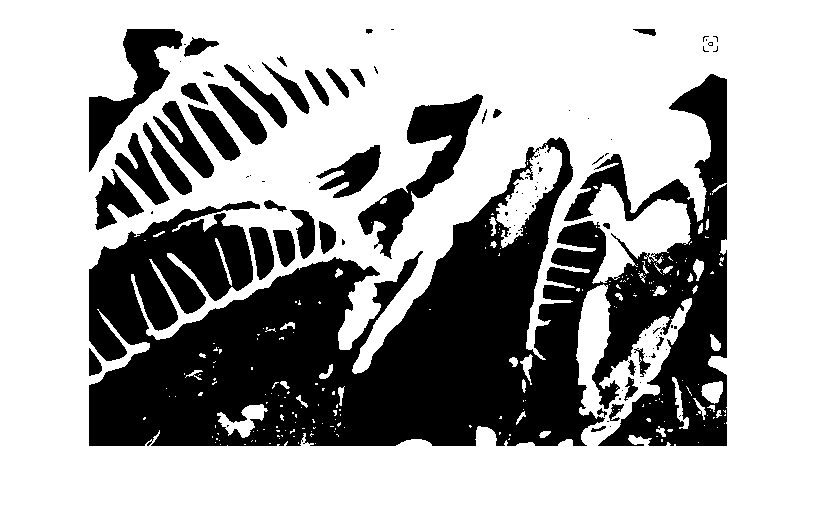

% Método Otsu: El método de Otsu elige un umbral que minimiza la 
% varianza interclase de los píxeles blancos y negros pasados por el
% umbral

Treshold     = graythresh(Gray_Image); % Calcula el umbral utilizando el
                                       % método Otsu
Binary_Image = imbinarize(Gray_Image, Treshold);
imshow(Binary_Image)

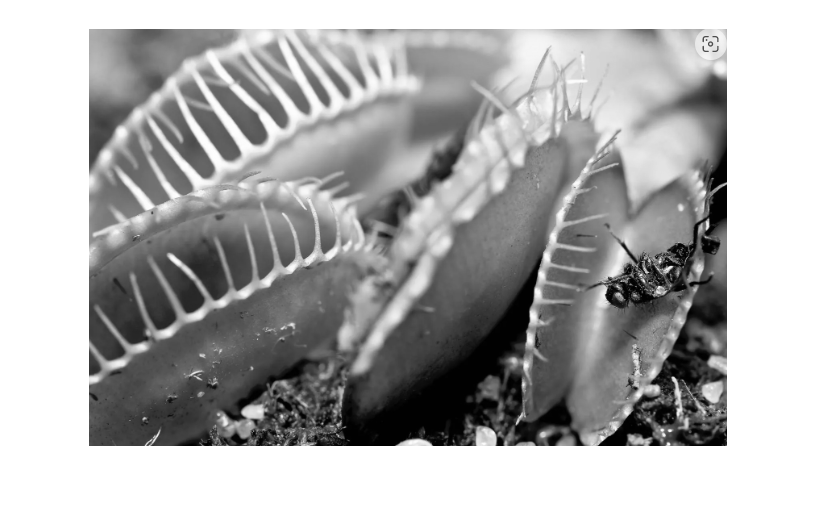

% Segmentacion por Crecimiento de Región
%I = double(Gray_Image);
I = Gray_Image;
imshow(Gray_Image);

[y,x] = getpts(); % Se obtiene el pixel Inicial o Semilla 

x = floor(x);
y = floor(y);

% Disimilitud Maxima permisible: Representa la mayor diferencia posible a
% partir de la cual 2 pixeles se consideran como semejantes.
Mp = 0.25; 

J = zeros(size(I));
I_sizes = size(I);

Srs = I(x,y) % Valor inicial de la semilla (0 a 255)

Srs = uint8
104

R = 1; % pixeles por region

R = 1


neg_free = 10000; neg_pos = 0;

L = zeros(neg_free);

L =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


pixdist = 0;
V = [-1,0; 1,0; 0,-1; 0,1];

V =     -1     0
     1     0
     0    -1
     0     1



while(pixdist < Mp && R < numel(I))
    for j = 1:4
        xn = x + V(j,1);
        yn = y + V(j,2);
ins = (xn>=1)&&(yn>=1)&&(xn<=I_sizes(1))&&(yn<=I_sizes(2));

    if(ins&&(J(xn,yn)==0))
        neg_pos = neg_pos+1;
        L(neg_pos,:) = [xn yn (xn,yn)]:
        J(xn,yn) = 1;
        end
    end

    end
end

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.